# Analysing the Visual Coding - 2P dataset from the Allen Brain Observatory 

The Allen Brain Observatory resource [1] comprises datasets of neural activity obtained from the mouse visual cortex collected during visual stimulus presentation. The Visual Coding - 2P dataset [2] consists of neural activity recordings obtained using two-photon calcium imaging:

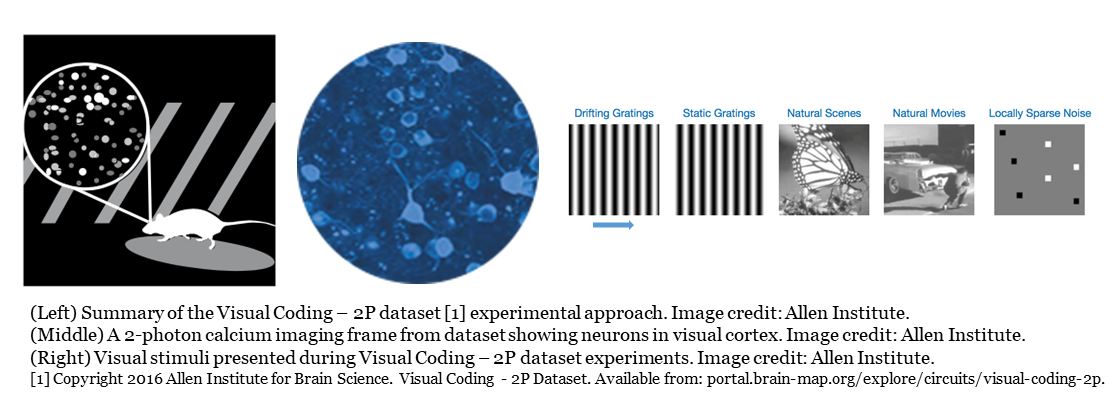

These recordings were obtained from a range of mouse visual areas, at a range of imaging depths, with indicator expression produced under several transgenic lines, and using a number of visual stimuli. For detailed information about experimental conditions and stimuli to date, see the Visual Coding - 2P dataset website: [https://portal.brain-map.org/explore/circuits/visual-coding-2p](https://portal.brain-map.org/explore/circuits/visual-coding-2p). 

This example demonstrates how to access, search, and filter data from the Visual Coding - 2P dataset using the [Brain Observatory Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox) (BOT). It also shows how to perform some simple analyses of visual responses by neurons in mouse primary visual cortex. Neural response properties such as orientation tuning are quantified, along with basic behavioural analysis.

## **Access the Allen Brain Observatory dataset**

Accessing the Visual Coding - 2P dataset with the BOT begins by initializing an instance of the `bot.ophysmanifest `class. This retrieves tables of the available experimental *sessions *and *containers:* 

% Obtain the manifest table of experimental sessions
sessions = bot.fetchSessions('ophys');

% Show an overview of the sessions available
head(sessions)

ans = 8×16 table
    type     date_of_acquisition     experiment_container_id    fail_eye_tracking       id        imaging_depth                    name                     specimen_id      stimulus_name                                    storage_directory                                  targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen          cre_line    
    _____    ____________________    _______________________    _________________    _________    _____________    _____________________________________    ___________    

The table variables provide information for each session, such as the imaging depth and the targeted visual area brain structure. Casting such values into `categorical` variables makes it easy to show a summary of the counts for each unique value:

% Show a summary of the sessions by imaging depth
summary(categorical(sessions.imaging_depth));

     175      336 
     185        3 
     195        3 
     200        3 
     205        6 
     225        3 
     250       12 
     265        6 
     275      549 
     276        3 
     285        3 
     300       15 
     320        3 
     325       12 
     335        9 
     350      144 
     365        3 
     375      336 
     390        3 
     400        9 
     435        3 
     550       39 
     570        6 
     625        9 


The majority of sessions were collected at imaging depths of 175, 275, 350, and 375$\mu$m. Several (39) sessions were also collected deeper into the cortical column at 550$\mu$m.

% Show a summary of the sessions by targeted structure
summary(categorical(sessions.targeted_structure_id));

     385      510 
     394      120 
     402      138 
     409      345 
     417      123 
     533      282 


## **Filter by cortical area and layer, visual stimulus, and behavioural tracking**

Our goal for this example is to analyse visually responsive neurons in primary visual cortex (V1) for orientation and direction selectivity. These selectivities are reported to be most pronounced in the anterolateral (AL), rostrolateral (RL), and anteromedial (AM) areas of V1 [3]. This analysis seeks a dataset from these areas in which drifting grating stimuli were presented and where the behavioural state of the animal was tracked. Searching and selecting experimental data is accomplished via [table access operations](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html): 

% Select experiments from the most orientation/direction-selective areas of visual cortex ('VISal', id = 402; 'VISrl', id = 417 ; 'VISam', id = 394 )
sessions = sessions(ismember(sessions.targeted_structure_id, [394 402 417]), :);

% Select experiments with GCaMP6f expression enriched in Layer 2/3 and Layer 4 of cortex
sessions = sessions(sessions.cre_line == "Cux2-CreERT2", :);

% Select experiments imaging from the shallowest depth in Layer 2/3
sessions = sessions(sessions.imaging_depth == 175,:);

% Select experiments with eye tracking data available
sessions = sessions(~sessions.fail_eye_tracking, :);

% Select experiments with drifting grating and natural movie stimuli
sessions = sessions(sessions.stimulus_name == "three_session_A", :);

Following these selection operations, we have identified two available sessions:

disp(sessions);

    type     date_of_acquisition     experiment_container_id    fail_eye_tracking       id        imaging_depth                      name                      specimen_id      stimulus_name                                                storage_directory                                               targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen         cre_line   
    _____    ____________________    _______________________    _________________    _________    _____________    ________________________________________    ___________

For the rest of this example, we'll work with the first of these identified sessions, which was obtained by Allen Institute researchers in February 2016:

session = bot.session(sessions(1,:));
session.metadata

ans = struct with fields:
                       type: OPhys
        date_of_acquisition: 23-Feb-2016 19:10:20
    experiment_container_id: 511510695
          fail_eye_tracking: 0
                         id: 503412730
              imaging_depth: 175
                       name: "20160223_222425_3StimA"
                specimen_id: 495727000
              stimulus_name: "three_session_A"
          storage_directory: "/external/neuralcoding/prod6/specimen_495727000/ophys_experiment_503412730/"
      targeted_structure_id: 402
       experiment_container: [1×1 struct]
           well_known_files: [3×1 struct]
         targeted_structure: [1×1 struct]
                   specimen: [1×1 struct]
                   cre_line: "Cux2-CreERT2"


## Extract neuron cell body regions-of-interest (ROIs) from imaged volume

Let's look at the imaged field, by visualizing the maximum intensity projection of the image volume. By examining the session metadata we can see the field of view is 400x400µm (512x512 pixels). We can plot a scale bar appropriately.

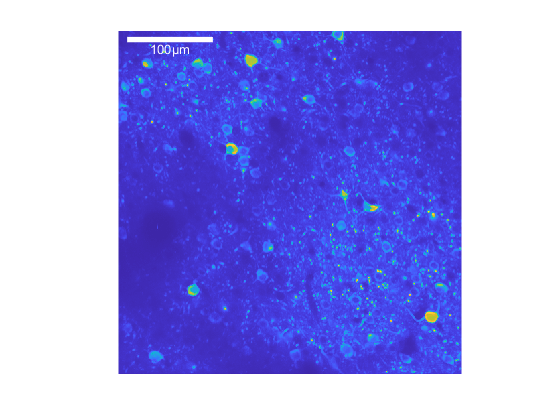

pixelSize = 400/512;
xLocations = linspace(0, 400-pixelSize, 512) + pixelSize / 2;
figure;
imagesc(xLocations, xLocations, session.max_projection);
colormap default;
axis square tight off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

Helpfully, the locations and shapes of ROIs defining each neuron's cell body are supplied to us from the Allen Brain Observatory data. We can access these ROIs using the `get_roi_mask `method which returns these ROIs as a 3-D connected components structure (`bwconncomp`). These can be plotted and manipulated by Image Processing Toolbox commands such as `labelmatrix.`

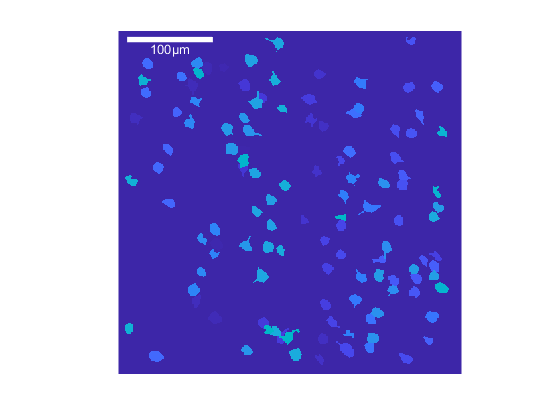

if license('test', 'image_toolbox')
   ROIs = session.roi_mask;
   figure;
   image(xLocations, xLocations, labelmatrix(ROIs));
   
   axis tight square off;
   hold all;
   plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
   text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');
end

## Assess neuron responses via calcium imaging fluorescence signals

Now let's get access to the fluorescence signals for each of the neuron ROIs, using the `get_dff_traces` method. This method returns a `[Tx1]` vector of timestamps, and a `[TxN]` matrix of fluorescence responses for each neuron, at each corresponding timestamp.

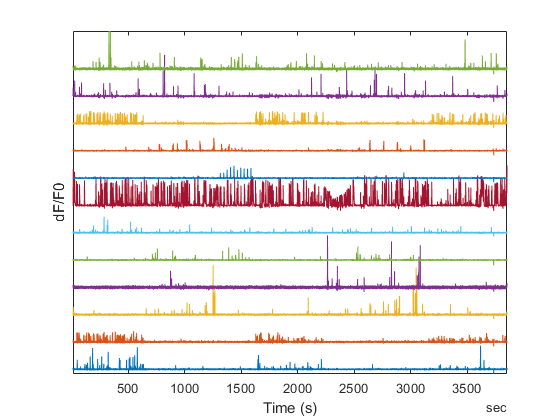

traces = session.dff_traces;
timestamps = session.fluorescence_timestamps;
figure;
plot(timestamps, traces(:, 1:10:end) + (1:10:size(traces, 2))/3)
axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

Not all neurons respond equally, as is clear from the traces above. One approach to select ROIs with robust responses is to measure the sample skewness of the individual responses over time. Neurons that fire sparsely result in a rapid spike in fluorescence emitted photons, followed by an exponential decay of fluorescence down to the noise level of the system. The resulting distribution of recorded fluorescence values has a positively skewed distribution, compared with Normally distributed white noise which has a theoretical skewness of zero. We can use the `skewness` function from the Statistics and Machine Learning Toolbox to estimate the sample skewness for each ROI.

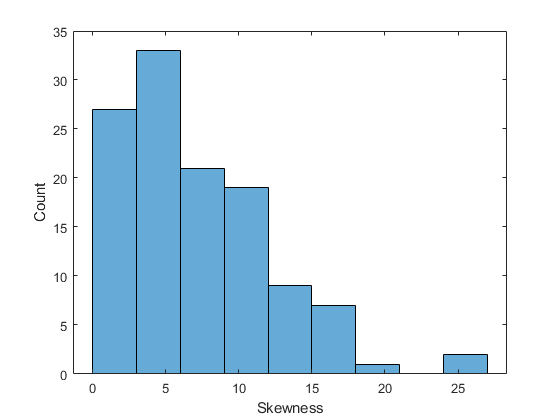

respSkewness = skewness(traces);
figure;
histogram(respSkewness);
xlabel('Skewness'); ylabel('Count')

Let's compare the response of a high-skewness ROI with that of a low-skewness ROI.

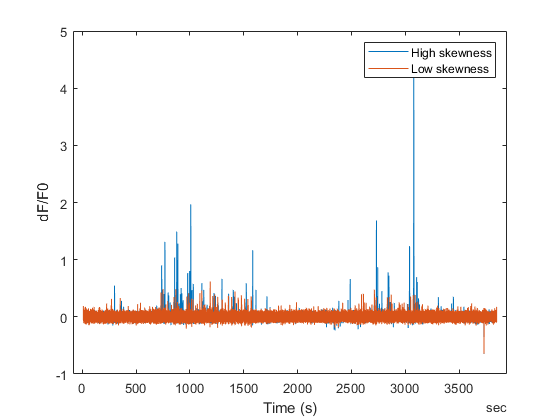

[~, sortOrder] = sort(respSkewness);
figure;
plot(timestamps, traces(:, sortOrder([end 5])))
xlabel('Time (s)'); ylabel('dF/F0');
legend('High skewness', 'Low skewness');

Generally a skewness threshold of 1 or 2 is sufficient, which is passed by the majority of neurons in this experiment.

## Analyse neuron stimulus responses for varying synthetic visual stimuli

This animal was presented with an array of stimuli, including drifting sine-wave grating stimuli. Let's find the responses to individual trials of the drifting gratings, separated by drift direction, and build tuning curves for each ROI.

% Get the stimulus information for drifting grating responses
driftingGratings = session.fetch_stimulus_table('drifting_gratings');

% Use a utility function to estimate single-trial responses for each stimulus
responses = bot.util.StimulusAlignedResp(driftingGratings, traces);

% Locate "blank" stimulus presentations
blankPresentations = driftingGratings.blank_sweep == 1;

% Extract neural responses to blank presentations
blankResponses = mean(responses(blankPresentations, :),'omitnan');

% Subtract blank responses
responsesCorrected = responses - blankResponses;

Each particular visual stimulus was presented multiple times. We therefore need to collect and sort responses to multiple trials of the same visual stimulus. We will assign a unique stimulus ID to each stimulus, using the built-in function `unique`. We can then collect all the single-trial responses for the stimuli.

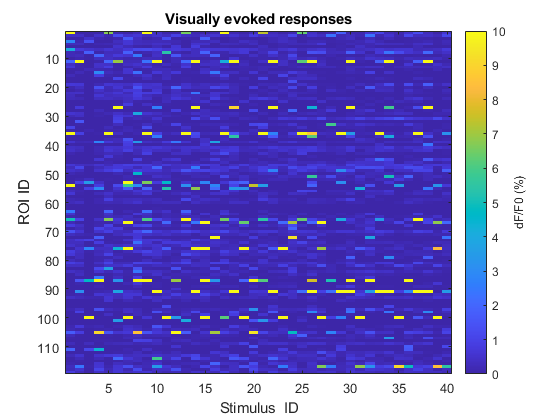

% Get a list of unique stimulus parameters and assign a stimulus ID to each presentation
[uniqueStimuli, ~, presentationStimID] = unique(driftingGratings(:, 1:2), 'rows', 'sorted');

% Find NAN stimuli and remove them
nanStimuli = isnan(uniqueStimuli.temporal_frequency);
uniqueStimuli = uniqueStimuli(~nanStimuli, :);
numStimuli = size(uniqueStimuli, 1);
numROIs = size(responsesCorrected, 2);

% Preallocate arrays
singleTrialResponses = cell(numStimuli, 1);
meanStimulusResponses = nan(numStimuli, numROIs);
varStimulusResponses = nan(numStimuli, numROIs);

% Collect single-trial responses for each stimulus
for stimulusID = 1:size(uniqueStimuli, 1)
    % Find the presentations of this stimulus
    theseTrials = presentationStimID == stimulusID;
    
    % Collect all the fluorescence responses for this stimulus into a cell array
    singleTrialResponses{stimulusID} = responsesCorrected(theseTrials, :);
    
    % Estimate response statistics for this stimulus
    meanStimulusResponses(stimulusID, :) = mean(singleTrialResponses{stimulusID},'omitnan');
    varStimulusResponses(stimulusID, :) = var(singleTrialResponses{stimulusID},'omitnan');
end

% Visualise the mean responses
figure;
imagesc(meanStimulusResponses' * 100);
xlabel('Stimulus  ID');
ylabel('ROI ID');
title('Visually evoked responses')
caxis([0 10]);
ax = colorbar;
ylabel(ax, 'dF/F0 (%)')

## Compute direction selectivity and orientation selectivity of individual neurons

Now we will use our knowledge of the stimuli to assign a selectivity measure of directional tuning to each ROI ([Hashemi-Nezhad & Lyon 2011](http://dx.doi.org/10.1093/cercor/bhr105)). These values range between 0 and 1, and indicate how strongly a ROI prefers a particular visual stimulus over others. Values close to 0 indicate no preference. Values close to 1 indicate a strong selective prefence for some stimuli. We will estimate two metrics — one to test whether ROIs prefer particular directions of drift of the moving gratings (a "direction selectivity index" or DSI); the second tests whether ROIs prefer particular orientations of the gratings, regardless of drift direction (an "orientation selectivity index" or OSI).

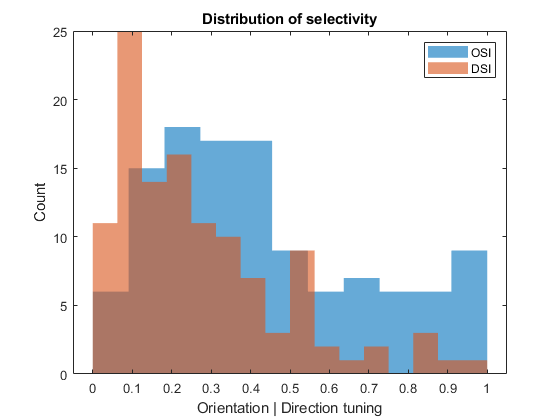

% Generate direction and orientation selectivity indices
stimDirection = exp(-1i * deg2rad(uniqueStimuli.orientation));
stimOrientation = exp(-1i * deg2rad(2*uniqueStimuli.orientation));
dirSelectivityIndex = abs(sum(max(0, meanStimulusResponses) .* stimDirection)) ./ sum(max(0, meanStimulusResponses));
oriSelectivityIndex = abs(sum(max(0, meanStimulusResponses) .* stimOrientation)) ./ sum(max(0, meanStimulusResponses));

% Plot the distribution of selectivity indices
figure;
bins = linspace(0, 1, 15);
histogram(oriSelectivityIndex, linspace(0, 1, 12), 'EdgeColor', 'none');
hold all;
histogram(dirSelectivityIndex, linspace(0, 1, 17), 'EdgeCOlor', 'none');
xlabel('Orientation | Direction tuning');
ylabel('Count');
title('Distribution of selectivity');
legend('OSI', 'DSI');

We can see that more neurons are orientation-tuned (high values for OSI, in blue), than direction tuned (high values for DSI, in orange), as described in prior literature [3]. 

Now we will examine the responses and tuning of neurons, by plotting *tuning curves* for direction and for temporal frequency. 

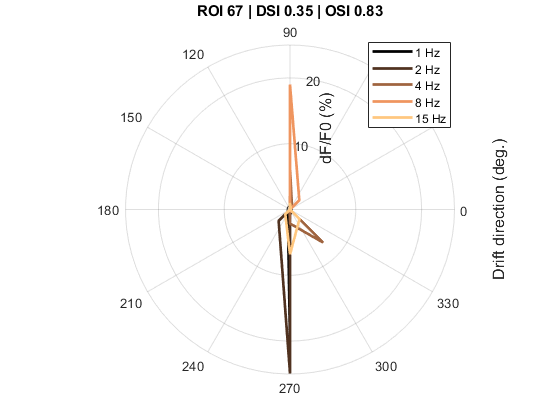

% Determine preferred direction for each ROI
dirPreference = angle(sum(max(0, meanStimulusResponses) .* stimDirection));
[~, dirSortOrder] = sort(dirPreference);

% Plot tuning curves for an interesting ROI
neuronIDPlot = 67;
figure;
plot_dir_tuning_curve(neuronIDPlot, uniqueStimuli, meanStimulusResponses);
title(sprintf('ROI %d | DSI %.2f | OSI %.2f', neuronIDPlot, dirSelectivityIndex(neuronIDPlot), oriSelectivityIndex(neuronIDPlot)))

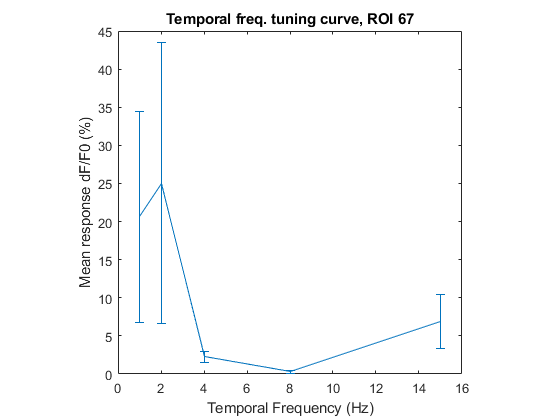

% Plot a temporal frequency tuning curve at preferred direction, showing SEM over single-trial responses
figure;
plot_tf_tuning_curve(neuronIDPlot, driftingGratings, responses);

The TF tuning curve is plotted for the stimuli matching the ROI's preferred drift direction. We can see that this ROI responds more strongly to faster drifting gratings (higher temporal frequency).

**Interactive tuning curve plot**

Now we will show how to quickly scrub through ROI response, by making use of an interactive slider. We generate a tuning curve figure, and update the plotted data on the fly without generating a new figure.

% Pre-compute several tuning curves for highly-tuned neurons
useNeurons = max(oriSelectivityIndex, dirSelectivityIndex) > 0.7;
useNeurons = useNeurons & max(meanStimulusResponses) > .1;
[dirTuningCurves, temporalFrequencies, driftDirections] = ...
    dir_tuning_curves(uniqueStimuli, meanStimulusResponses(:, useNeurons));
curves = [];

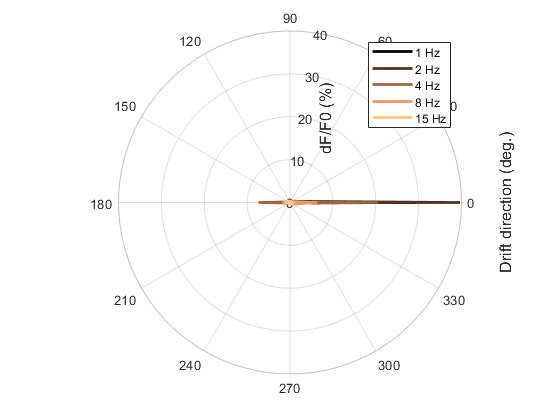

% Quickly update the tuning curve to show a different ROI
neuronIDPlot = 1;
if neuronIDPlot > nnz(useNeurons), neuronIDPlot = nnz(useNeurons); end
curves = update_tuning_curve(curves, dirTuningCurves(:, :, neuronIDPlot) * 100, uniqueStimuli, meanStimulusResponses);

## Assess correlation of pupil diameter behavioural signal with neural signal

Allen Brain Observatory data for each experiment contains not only visually-evoked responses, but also records aspects of the animal's motor output during the course of the experiment. Here we example changes in pupil size over time, which is considered by some to be a measure of attention or arousal ([van den Brink et al. 2016](https://doi.org/10.1371/journal.pone.0165274) and references therein).

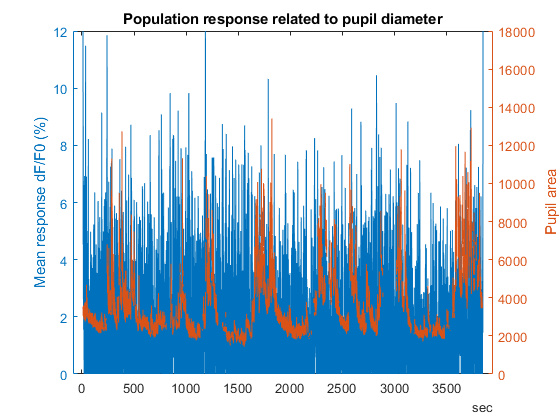

% Get a pupil area trace
pupilArea = session.pupil_size;

% Visualise the pupil area over time, along with population mean activity
meanRespPop = mean(traces, 2,'omitnan');
figure;
yyaxis left;
plot(timestamps, meanRespPop * 100);
ylim([0 12]);
ylabel('Mean response dF/F0 (%)');
yyaxis right;
plot(timestamps, pupilArea);
ylabel('Pupil area');
title('Population response related to pupil diameter');

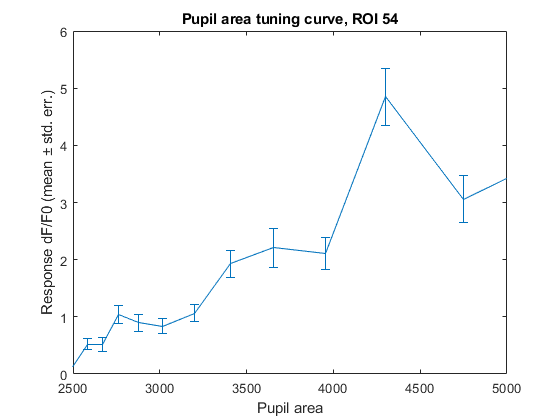

% Find a neuron that correlates with pupil area
pupilCorr = corr(pupilArea, traces, 'rows', 'complete');
[~, neuronID] = max(pupilCorr);

% Bin time according to pupil diameter, with equal samples per bin
numBins = 20;
binsPupil = prctile(pupilArea, linspace(0, 100, numBins));
binCentresPupil = (binsPupil(1:end-1) + binsPupil(2:end)) / 2;
assignBins = discretize(pupilArea, binsPupil);
useBins = ~isnan(assignBins);
meanRespPupil = accumarray(assignBins(useBins), traces(useBins, neuronID), [], @(x)mean(x,'omitnan'));
stdRespPupil = accumarray(assignBins(useBins), traces(useBins, neuronID), [], @(x)std(x,'omitnan'));
binCounts = accumarray(assignBins(useBins), 1);

% Visualise neuron response associated with pupil area
figure;
errorbar(binCentresPupil, 100 * meanRespPupil, 100 * stdRespPupil ./ sqrt(binCounts));
xlim([.25 .5]*1e4);
xlabel('Pupil area');
ylabel('Response dF/F0 (mean ± std. err.)');
title(sprintf('Pupil area tuning curve, ROI %d', neuronID));

## Natural movie responses

Many experimental sessions also contain activity recorded in response to natural movie stimuli. Here we will briefly visualise the complex population responses to natural movies, and plot the responses of a cell with reliable responses to natural movies.

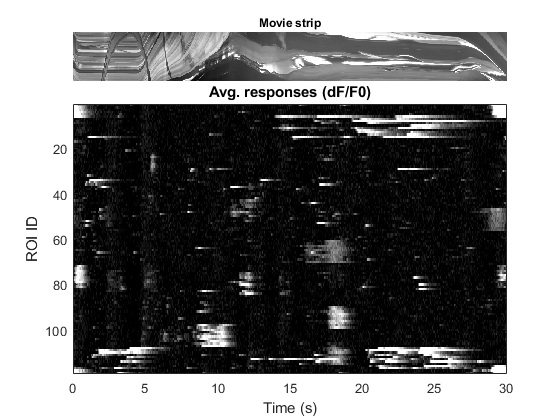

% Get the stimulus information for a natural movie stimulus
naturalMovieOne = session.fetch_stimulus_table('natural_movie_one');

% Use a utility function to estimate single-trial responses for each stimulus
responsesMovie = bot.util.StimulusAlignedResp(naturalMovieOne, traces, [], [], true);

% Reshape into tensor of [movie frame, ROI, trial]
numTrials = max(naturalMovieOne.repeat) + 1;
responsesMovie = reshape(responsesMovie, [], numROIs, numTrials);
numMovieFrames = size(responsesMovie, 1);
meanRespMovie = mean(responsesMovie, 3, 'omitnan');

% Get the movie frames from the stimulus
movie = session.fetch_stimulus_template('natural_movie_one');

% Make a time trace for the movie
startTime = timestamps(naturalMovieOne.start_frame(1));
endTrialFrame = find(naturalMovieOne.repeat == 0, 1, 'last');
endTime = timestamps(naturalMovieOne.end_frame(endTrialFrame));
endTime = endTime - startTime;
timeTraceMovie = seconds(linspace(0, endTime, numMovieFrames));

% Make a figure showing the mean responses
figure;
subplot(5, 1, 1);
imagesc(make_movie_strip(movie));
colormap gray
title('Movie strip')
axis off;
subplot(5, 1, 2:5);
imagesc(timeTraceMovie, 1:numROIs, meanRespMovie' * 100);
title('Avg. responses (dF/F0)');
xlabel('Time (s)');
ylabel('ROI ID');
caxis([0 20]);

**Estimate response reliability**

We can generate a metric for response reliability, using trail-to-trial correlations in response to natural movie stimuli. This will help us pick out ROIs that are visually responsive to natural movies, under the assumption that they should respond similarly across trials.

Response reliability is defined as the average pairwise correlation coefficient between time traces of all single-trial responses for a given ROI.

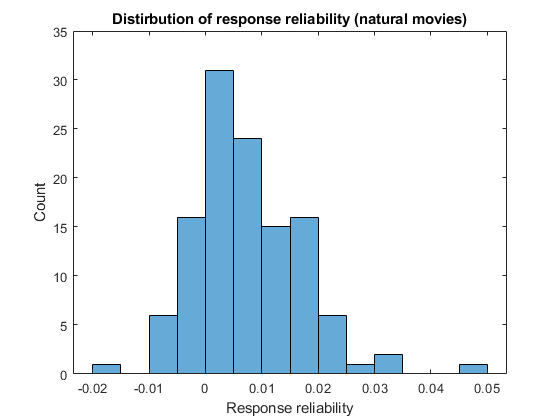

% Compute response reliability
reliabilityMovie = nan(1, numROIs);
for roiID = 1:numROIs
    reliabilityMovie(roiID) = movie_response_reliability(responsesMovie(:, roiID, :));
end

% Show a histogram of response reliabilities
figure;
histogram(reliabilityMovie);
title('Distirbution of response reliability (natural movies)')
xlabel('Response reliability');
ylabel('Count');

**Plot the single-trial natural movie responses for a cell**

Trial-to-trial correlations are fairly low for most ROIs. Let's show the responses of one ROI that responds strongly, and has a relatively high response reliability.

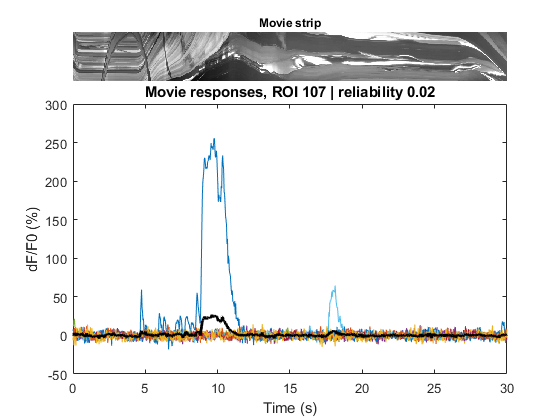

% Plot the single-trial responses for a single cell
cellID = 107;

figure;
subplot(5, 1, 1);
imagesc(make_movie_strip(movie));
colormap gray;
title('Movie strip')
axis off;
subplot(5, 1, 2:5);
plot(timeTraceMovie, squeeze(responsesMovie(:, cellID, :)) * 100);
hold all;
plot(timeTraceMovie, meanRespMovie(:, cellID) * 100, 'k-', 'LineWidth', 2);
xlim(seconds([0 endTime]))
title(sprintf('Movie responses, ROI %d | reliability %.2f', cellID, reliabilityMovie(cellID)));
xlabel('Time (s)');
ylabel('dF/F0 (%)');

## Utility functions

function [dirTuningCurves, temporalFrequencies, driftDirections] = ...
    dir_tuning_curves(uniqueStimuli, meanStimulusResponses)
    % Function to calculate direction tuning curves over temporal frequencies
    
    % Extract temporal frequencies and drift directions
    [temporalFrequencies, ~, tempFreqIDs] = unique(uniqueStimuli.temporal_frequency);
    temporalFrequencies = temporalFrequencies(~isnan(temporalFrequencies));
    [driftDirections, ~, driftDirIDs] = unique(uniqueStimuli.orientation);
    driftDirections = deg2rad(driftDirections);
    
    % Make an index for ROI ID
    numROIs = size(meanStimulusResponses, 2);
    roiIDs = permute(1:numROIs, [2 3 1]);
    [tempFreqIndex, roiIndex] = ndgrid(tempFreqIDs, roiIDs);
    [driftDirIndex, ~] = ndgrid(driftDirIDs, roiIDs);
    
    % Clip responses at zero
    meanStimulusResponses = max(0, meanStimulusResponses);
    
    % Build a tensor of tuning curves
    dirTuningCurves = accumarray(...
        {driftDirIndex(:), tempFreqIndex(:), roiIndex(:)}, ...
        meanStimulusResponses(:), ...
        [numel(driftDirections), numel(temporalFrequencies), numROIs]);
end

function curves = plot_dir_tuning_curve(exampleROI, uniqueStimuli, meanStimulusResponses)
    % Function to plot a direction tuning curve

    % Get a tuning curve for this ROI
    [dirTuningCurves, temporalFrequencies, driftDirections] = ...
        dir_tuning_curves(uniqueStimuli, meanStimulusResponses(:, exampleROI));
    
    % Make a color map for the temporal frequencies
    colors = copper(length(temporalFrequencies));
    
    % Loop over temporal frequencies
    for temporalFreqID = 1:length(temporalFrequencies)
        curves(temporalFreqID) = polarplot(driftDirections([1:end 1]), dirTuningCurves([1:end 1], temporalFreqID) * 100, ...
                  'LineWidth', 2, ...
                  'Color', colors(temporalFreqID, :)); %#ok<AGROW> 
        hold on;        
    end
    
    % Make the plot prettier
    a = gca;
    a.RAxis.Label.String = 'dF/F0 (%)';
    a.ThetaAxis.Label.String = 'Drift direction (deg.)';
    
    % Add a temporal frequency legend
    legendText = arrayfun(@(tf)sprintf('%d Hz', tf), temporalFrequencies, 'UniformOutput', false);
    legend(legendText, 'location', 'northeast');
end

function curves = update_tuning_curve(curves, newTuningCurve, uniqueStimuli, meanStimulusResponses)
    % Function to generate or update a tuning curve plot
    if isempty(curves)
        figure;
        curves = plot_dir_tuning_curve(1, uniqueStimuli, meanStimulusResponses);
    end
    
    % Function to modify an existing tuning curve plot
    for temporalFreqID = 1:size(newTuningCurve, 2)
        curves(temporalFreqID).RData = newTuningCurve([1:end 1], temporalFreqID);
    end    
end

% Function to plot a temporal frequency tuning curve at the preferred direction
function plot_tf_tuning_curve(exampleROI, stimuli, responses)
    % Find the preferred direction for the chosen ROI
    respROI = responses(:, exampleROI);
    [~, ~, directionID] = unique(stimuli.orientation);
    sumRespDir = accumarray(directionID, respROI);
    [~, prefDir] = max(sumRespDir,[],'omitnan');
    prefDirResps = directionID == prefDir;
    
    % Collect responses over temporal frequencies
    [temporalFrequencies, ~, tfIDs] = unique(stimuli.temporal_frequency(prefDirResps));
    meanRespTF = accumarray(tfIDs, respROI(prefDirResps), [], @(x)mean(x,'omitnan'));
    stdRespTF = accumarray(tfIDs, respROI(prefDirResps), [], @(x)std(x,'omitnan'));
    countRespTF = accumarray(tfIDs, 1);
    
    % Plot TF tuning curve
    errorbar(temporalFrequencies, 100* meanRespTF, 100 * stdRespTF ./ sqrt(countRespTF));
    xlabel('Temporal Frequency (Hz)');
    ylabel('Mean response dF/F0 (%)');
    title(sprintf('Temporal freq. tuning curve, ROI %d', exampleROI));
    xlim([0 max(temporalFrequencies)+1]);
    axis square;
end

% Function to generate a natural movie strip
function strip = make_movie_strip(movie)
    halfFrame = round(size(movie, 2) / 2);
    strip = squeeze(movie(:, halfFrame, :));
end

function reliability = movie_response_reliability(responses)
    % Function to compute response reliability
    % `responses` is [time x trials]
    corrs = corrcoef(squeeze(responses));
    takeCorrs = triu(true(size(corrs)), 1);
    reliability = mean(corrs(takeCorrs),'omitnan');
end

## References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[2] Copyright 2016 Allen Institute for Brain Science. Visual Coding - 2P Dataset. Available from: [portal.brain-map.org/explore/circuits/visual-coding-2p](https://portal.brain-map.org/explore/circuits/visual-coding-2p).

[3] Marshal, J.H., Garrett, M.E., Nauhaus, I., and Callaway, E.M. (2011). Functional Specialization of Seven Mouse Visual Cortical Areas. *Neuron* 72 (6): 1040. [https://dx.doi.org/10.1016%2Fj.neuron.2011.12.004.](https://dx.doi.org/10.1016%2Fj.neuron.2011.12.004.) 